# S1: - Stability analysis depending on k

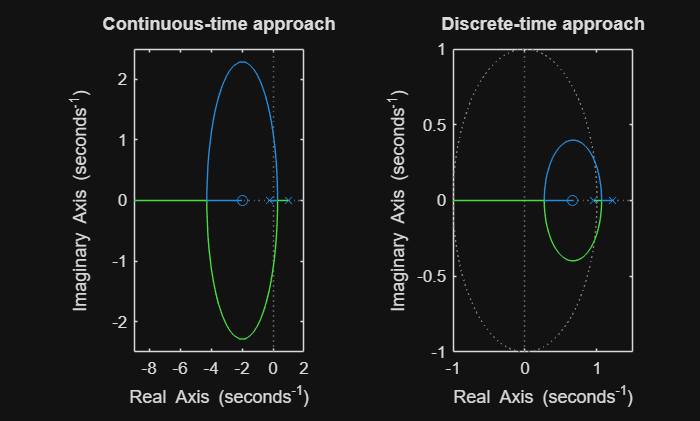

clear; % erase all the existing workspace variables
num = [1 2]; den = [4 -3 -1]; % the nominator and denominator of the process
Hp = tf(num,den); % the process transfer function
T = 0.2; % the sampling period
Hdes = c2d(Hp, T, 'zoh'); % the open loop discrete time transfer function
subplot(121); rlocus(Hp); title('Continuous-time approach');
text(-8,2,'$H_{des}(s)=\frac{s+2}{(4s+1)(s-1)}$','Interpreter','Latex','FontSize',18)
subplot(122); rlocus(Hdes); title('Discrete-time approach')
text(0.2,0.8,'$H_{des}(z)=\frac{0.064563 (z-0.6655)}{(z-1.221) (z-0.9512)}$','Interpreter','Latex','FontSize',18)

zpk(Hdes) % tf - products of zeros and poles


ans =
 
  0.064563 (z-0.6655)
  --------------------
  (z-1.221) (z-0.9512)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.


## Unstable case, k = 2;

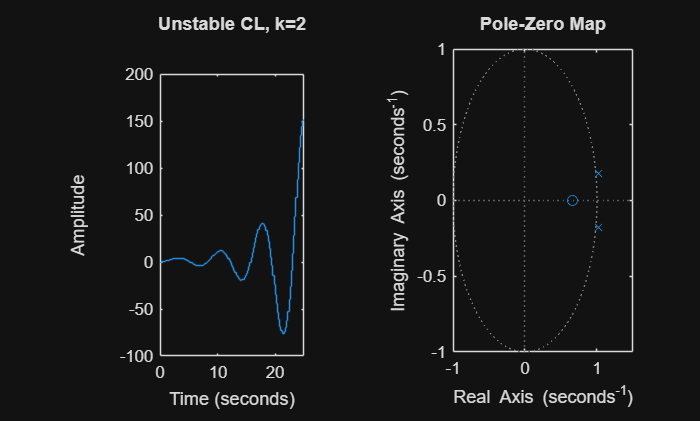

clc
close all

k = 2;

% step(feedback(k*Hdes, 1));
% title('Unstable CL')
% zoom in the first 25 seconds
% figure;
Ho = feedback(k*Hdes, 1);
% step(Ho, 25); % only for discrete tf it works (it means final t)
% title('Unstable CL, k=2')

figure,
subplot(121); step(Ho, 25); title('Unstable CL, k=2')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - outside the unity circle (1.02 +- 0.179j)

## Undamped case, k = 3.76;

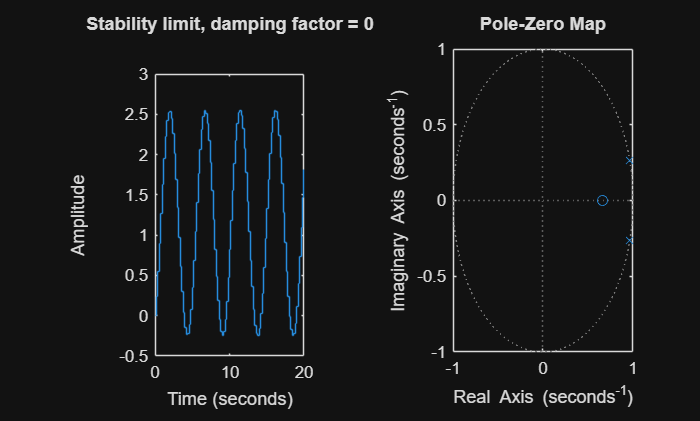

k = 3.76;
Ho = feedback(k*Hdes, 1);
figure,
subplot(121); step(Ho, 20); title('Stability limit, damping factor = 0')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - exactly on the unity circle (0.965 +- 0.263j)

## Underdamped case, k = 3.76;

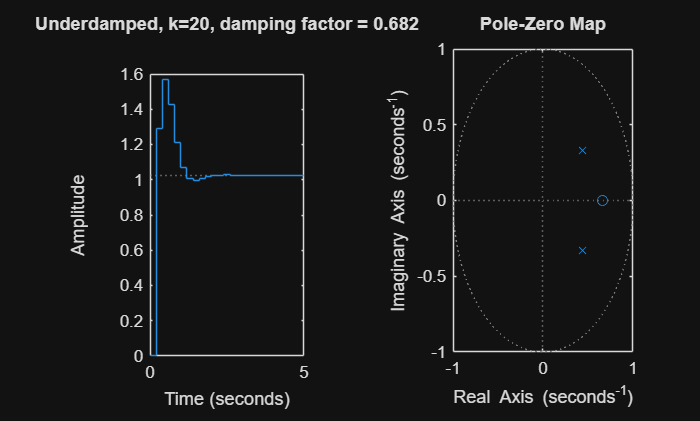

k = 20;
Ho = feedback(k*Hdes, 1);
figure,
subplot(121); step(Ho, 5); title('Underdamped, k=20, damping factor = 0.682')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle (0.441 +- 0.329j)

## Critically damped case, k = 25.38;

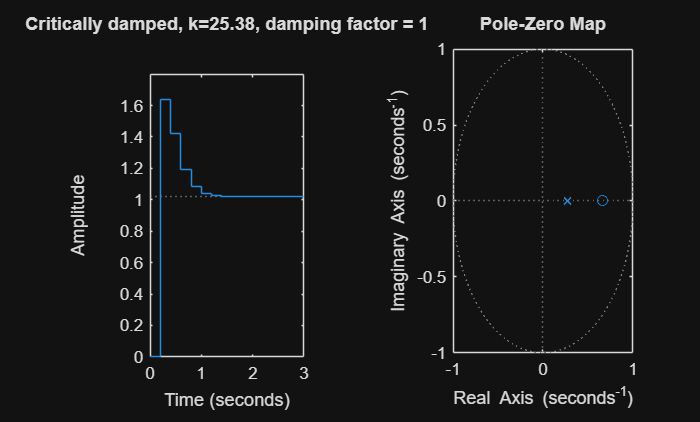

k = 25.38;
Ho = feedback(k*Hdes, 1);
figure,
subplot(121); step(Ho, 3); title('Critically damped, k=25.38, damping factor = 1')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle (equal real poles) (0.267)

## Overdamped case, k = 35;

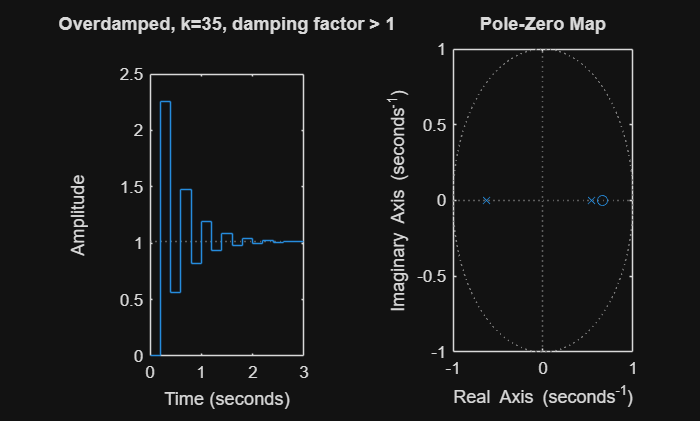

k = 35;
Ho = feedback(k*Hdes, 1);
figure,
subplot(121); step(Ho, 3); title('Overdamped, k=35, damping factor > 1')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle (real poles) (0.543 and -0.63)

## Undamped case, k = 40.3;

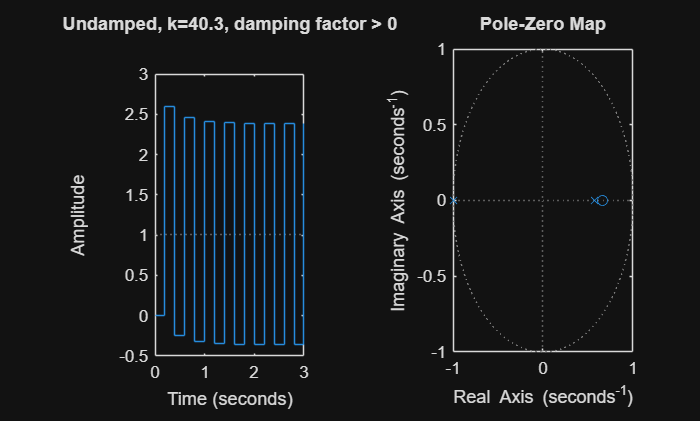

k = 40.3;
Ho = feedback(k*Hdes, 1);
figure,
subplot(121); step(Ho, 3); title('Undamped, k=40.3, damping factor > 0')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - one is heading to the zero (0.57)
%                              - the other one is on the unity circle (-1)